# Diagnostic Plots

Important part of data wrangling

Diagnostic plots help you identify outliers, and see other problems in your model or fit. For example, load the `carsmall` data, and make a model of `MPG` as a function of `Cylinders` (categorical) and `Weight`:

%load carsmall
%tbl = table(Weight,MPG,Cylinders);
%tbl.Cylinders = categorical(tbl.Cylinders);
%mdl = fitlm(tbl,'MPG ~ Cylinders*Weight + Weight^2');

Make a leverage plot of the data and model.

plotDiagnostics(mdl)

There are a few points with high leverage. But this plot does not reveal whether the high-leverage points are outliers.

Look for points with large Cook’s distance.

plotDiagnostics(mdl,'cookd')

There is one point with large Cook’s distance. Identify it and remove it from the model. You can use the Data Cursor to click the outlier and identify it, or identify it programmatically:

[~,larg] = max(mdl.Diagnostics.CooksDistance);

xnv=xv;
ynv=yv;
%remove data points
xnv(20)=[];
ynv(20)=[];

ntbl=table(ynv,xnv);

mdl2=fitlm(ntbl)
%mdl2 = fitlm(data,'mpg ~ cyl*wt + wt^2','Exclude',larg);

plotDiagnostics(mdl2,'cookd')

### Residuals — Model Quality for Training Data

There are several residual plots to help you discover errors, outliers, or correlations in the model or data. The simplest residual plots are the default histogram plot, which shows the range of the residuals and their frequencies, and the probability plot, which shows how the distribution of the residuals compares to a normal distribution with matched variance.

Examine the residuals:

plotResiduals(mdl2)

The observations above 12 are potential outliers.

plotResiduals(mdl2,'probability')

The two potential outliers appear on this plot as well. Otherwise, the probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals.

You can identify the two outliers and remove them from the data:

outl = find(mdl2.Residuals.Raw > 12)

To remove the outliers, use the `Exclude` name-value pair:

mdl3 = fitlm(ntbl,'MPG ~ Cylinders*Weight + Weight^2','Exclude',outl);

Examine a residuals plot of mdl2:

plotResiduals(mdl3)

The new residuals plot looks fairly symmetric, without obvious problems. However, there might be some serial correlation among the residuals. Create a new plot to see if such an effect exists.

plotResiduals(mdl3,'lagged')

The scatter plot shows many more crosses in the upper-right and lower-left quadrants than in the other two quadrants, indicating positive serial correlation among the residuals.

Another potential issue is when residuals are large for large observations. See if the current model has this issue.

plotResiduals(mdl3,'fitted')

There is some tendency for larger fitted values to have larger residuals. Perhaps the model errors are proportional to the measured values.

### Plots to Understand Predictor Effects

This example shows how to understand the effect each predictor has on a regression model using a variety of available plots. 

Examine a slice plot of the responses. This displays the effect of each predictor separately.

plotSlice(mdl)

You can drag the individual predictor values, which are represented by dashed blue vertical lines. You can also choose between simultaneous and non-simultaneous confidence bounds, which are represented by dashed red curves.

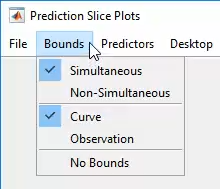

Use an effects plot to show another view of the effect of predictors on the response.

plotEffects(mdl)

This plot shows that changing `Weight` from about 2500 to 4732 lowers `MPG` by about 30 (the location of the upper blue circle). It also shows that changing the number of cylinders from 8 to 4 raises `MPG` by about 10 (the lower blue circle). The horizontal blue lines represent confidence intervals for these predictions. The predictions come from averaging over one predictor as the other is changed. In cases such as this, where the two predictors are correlated, be careful when interpreting the results.

Instead of viewing the effect of averaging over a predictor as the other is changed, examine the joint interaction in an interaction plot.

plotInteraction(mdl,'Weight','Cylinders')

The interaction plot shows the effect of changing one predictor with the other held fixed. In this case, the plot is much more informative. It shows, for example, that lowering the number of cylinders in a relatively light car (`Weight` = 1795) leads to an increase in mileage, but lowering the number of cylinders in a relatively heavy car (`Weight` = 4732) leads to a decrease in mileage.

For an even more detailed look at the interactions, look at an interaction plot with predictions. This plot holds one predictor fixed while varying the other, and plots the effect as a curve. Look at the interactions for various fixed numbers of cylinders.

plotInteraction(mdl,'Cylinders','Weight','predictions')

Now look at the interactions with various fixed levels of weight.

plotInteraction(mdl,'Weight','Cylinders','predictions')

### Plots to Understand Terms Effects

This example shows how to understand the effect of each term in a regression model using a variety of available plots.

Create an added variable plot with `Weight^2` as the added variable.

plotAdded(mdl,'Weight^2')

This plot shows the results of fitting both `Weight^2` and `MPG` to the terms other than `Weight^2`. The reason to use `plotAdded` is to understand what additional improvement in the model you get by adding `Weight^2`. The coefficient of a line fit to these points is the coefficient of `Weight^2` in the full model. The `Weight^2` predictor is just over the edge of significance (`pValue` < 0.05) as you can see in the coefficients table display. You can see that in the plot as well. The confidence bounds look like they could not contain a horizontal line (constant `y`), so a zero-slope model is not consistent with the data. 

Create an added variable plot for the model as a whole.

plotAdded(mdl)

The model as a whole is very significant, so the bounds don't come close to containing a horizontal line. The slope of the line is the slope of a fit to the predictors projected onto their best-fitting direction, or in other words, the norm of the coefficient vector. 

### Change Models

There are two ways to change a model:

- [`step`](docid:stats_ug.bszh9bd-1) — Add or subtract terms one at a time, where `step` chooses the most important term to add or remove.

- [`addTerms`](docid:stats_ug.bszh767-1) and [`removeTerms`](docid:stats_ug.bszh827-1) — Add or remove specified terms. Give the terms in any of the forms described in [Choose Model or Range of Models](docid:stats_ug.btc3kn5).

If you created a model using [`stepwiselm`](docid:stats_ug.bt0cpr2), then `step` can have an effect only if you give different upper or lower models. `step` does not work when you fit a model using `RobustOpts`.

For example, start with a linear model of mileage from the `carbig` data:

load carbig
tbl = table(Acceleration,Displacement,Horsepower,Weight,MPG);
mdl = fitlm(tbl,'linear','ResponseVar','MPG')

Try to improve the model using step for up to 10 steps:

mdl1 = step(mdl,'NSteps',10)

`step` stopped after just one change.

To try to simplify the model, remove the `Acceleration` and `Weight` terms from `mdl1`:

mdl2 = removeTerms(mdl1,'Acceleration + Weight')

`mdl2` uses just `Displacement` and `Horsepower`, and has nearly as good a fit to the data as `mdl1` in the `Adjusted R-Squared` metric.

# Principle Components Analysis

One of the difficulties inherent in multivariate statistics is the problem of visualizing data that has many variables. The MATLAB® function plot displays a graph of the relationship between two variables. The plot3 and surf commands display different three-dimensional views. But when there are more than three variables, it is more difficult to visualize their relationships.

Fortunately, in data sets with many variables, groups of variables often move together. One reason for this is that more than one variable might be measuring the same driving principle governing the behavior of the system. In many systems there are only a few such driving forces. But an abundance of instrumentation enables you to measure dozens of system variables. When this happens, you can take advantage of this redundancy of information. You can simplify the problem by replacing a group of variables with a single new variable.

Principal component analysis is a quantitatively rigorous method for achieving this simplification. The method generates a new set of variables, called principal components. Each principal component is a linear combination of the original variables. All the principal components are orthogonal to each other, so there is no redundant information. The principal components as a whole form an orthogonal basis for the space of the data.

**Principal component analysis** (**PCA**) is a statistical procedure that uses an [orthogonal transformation](https://en.wikipedia.org/wiki/Orthogonal_transformation) to convert a set of observations of possibly correlated variables (entities each of which takes on various numerical values) into a set of values of [linearly uncorrelated](https://en.wikipedia.org/wiki/Correlation_and_dependence) variables called **principal components**. This transformation is defined in such a way that the first principal component has the largest possible [variance](https://en.wikipedia.org/wiki/Variance) (that is, accounts for as much of the variability in the data as possible), and each succeeding component in turn has the highest variance possible under the constraint that it is [orthogonal](https://en.wikipedia.org/wiki/Orthogonal) to the preceding components. The resulting vectors (each being a [linear combination](https://en.wikipedia.org/wiki/Linear_combination) of the variables and containing *n* observations) are an uncorrelated [orthogonal basis set](https://en.wikipedia.org/wiki/Orthogonal_basis_set). PCA is sensitive to the relative scaling of the original variables.

data=readtable('../data/mtcars.csv')

x_values = 0:0.05:35;
pdmpg = fitdist(data.mpg,'Normal')
y = 1400*pdf(pdmpg,x_values)/7;

pca(table2array(data(:,2:12)))

varnames=data.Properties.VariableNames;
varind=[2 4 5 6 7 8]
plotindex=1;
figure;
for i=1:6
    for j=1:6
    varnamex=varnames{varind(i)};
    varnamey=varnames{varind(j)};
    
    x=data(1:end,{varnamex});
    y=data(1:end,{varnamey});
    
    subplot(6,6,plotindex);
    scatter(table2array(x),table2array(y));
    xlabel(varnamex)
    ylabel(varnamey)
    
    plotindex=plotindex+1;
    end
end

### Examine Quality and Adjust Fitted Model

After fitting a model, examine the result and make adjustments.

#### Model Display

A linear regression model shows several diagnostics when you enter its name or enter `disp(mdl)`. This display gives some of the basic information to check whether the fitted model represents the data adequately.

For example, fit a linear model to data constructed with two out of five predictors not present and with no intercept term:


mdllm = fitlm(x,y)

Notice that:

- The display contains the estimated values of each coefficient in the `Estimate` column. These values are reasonably near the true values `[0;1;0;3;0;-1]`.

- There is a standard error column for the coefficient estimates.

- The reported `pValue` (which are derived from the *t* statistics (`tStat`) under the assumption of normal errors) for predictors 1, 3, and 5 are extremely small. These are the three predictors that were used to create the response data `y`.

- The `pValue` for `(Intercept)`, `x2` and `x4` are much larger than 0.01. These three predictors were not used to create the response data `y`.

- The display contains $R^2$, adjusted $R^2$, and *F* statistics.